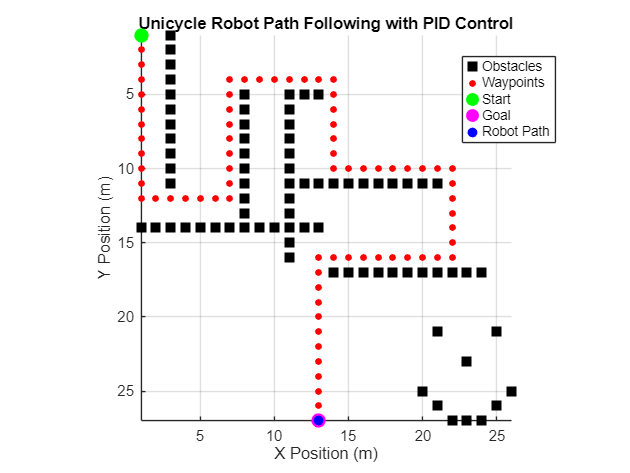

% PID controller Unicycle robot A* sim with motion

% Parameters
x = startNode(1);           % Initial x position from A* startNode
y = startNode(2);           % Initial y position from A* startNode
theta = 0;                  % Initial orientation

% PID Controller gains
k_v = 40;                   % Proportional gain for linear velocity
k_omega = 120;              % Proportional gain for angular velocity
k_vd = 0.4;                 % Derivative gain for linear velocity
k_omega_d = 0.4;            % Derivative gain for angular velocity
k_vi = 0.5;                 % Integral gain for linear velocity
k_omega_i = 30;             % Integral gain for angular velocity

% Simulation parameters
dt = 0.01;
max_time = 50;              % Adjust simulation duration as needed
t = 0:dt:max_time;

% Path from A* as waypoints
waypoints = path;           % Import waypoints as (x, y) from A* 'path' variable

% Preallocate memory
x_history = [];
y_history = [];
theta_history = [];
positionalErrors = [];      % Store positional errors
trackingErrors = [];        % Store tracking errors
goalReached = false;
epsilon_position = 0.1;     % Threshold for settling time
settlingTime = NaN;         % Default if goal not reached

% Previous errors and integral terms for PID control
e_distance_prev = 0;
e_angle_prev = 0;
int_e_distance = 0;
int_e_angle = 0;

% Initialize plot
figure;
hold on;

% Plot obstacles
[x_obstacles, y_obstacles] = find(environment == 1);
plot(x_obstacles, y_obstacles, 'ks', 'MarkerSize', 8, 'MarkerFaceColor', 'k');

% Plot waypoints
plot(waypoints(:,1), waypoints(:,2), 'ro', 'MarkerSize', 4, 'MarkerFaceColor', 'r');

% Highlight start and goal points
plot(waypoints(1,1), waypoints(1,2), 'go', 'MarkerSize', 9, 'MarkerFaceColor', 'g'); % Start
plot(waypoints(end,1), waypoints(end,2), 'mo', 'MarkerSize', 9, 'MarkerFaceColor', 'm'); % Goal

% Plot setup
xlabel('X Position (m)');
ylabel('Y Position (m)');
title('Unicycle Robot Path Following with PID Control');
grid on;
axis equal tight;
set(gca, 'YDir', 'reverse');

% Animation setup
robot_plot = plot(x, y, 'bo', 'MarkerSize', 6, 'MarkerFaceColor', 'b'); % Robot marker
path_plot = plot(x_history, y_history, 'b-', 'LineWidth', 1.5);          % Path line

% Loop through waypoints
for wp = 1:size(waypoints, 1)
    x_target = waypoints(wp, 1);
    y_target = waypoints(wp, 2);
    
    while true
        % Calculate errors
        e_x = x_target - x;
        e_y = y_target - y;
        e_distance = sqrt(e_x^2 + e_y^2);  % Positional error
        e_angle = atan2(e_y, e_x) - theta;
        e_angle = atan2(sin(e_angle), cos(e_angle)); % Wrap to [-pi, pi]
        
        % Tracking error: Closest point on path
        e_tracking = min(vecnorm(waypoints' - [x; y], 2, 1)); % Min distance to path
        trackingErrors = [trackingErrors, e_tracking];        % Store tracking error
        
        % Integral terms
        int_e_distance = int_e_distance + e_distance * dt;
        int_e_angle = int_e_angle + e_angle * dt;
        
        % Derivative terms
        de_distance = (e_distance - e_distance_prev) / dt; % Linear error rate
        de_angle = (e_angle - e_angle_prev) / dt;         % Angular error rate
        
        % PID control laws
        v = k_v * e_distance + k_vd * de_distance + k_vi * int_e_distance; % PID for linear velocity
        omega = k_omega * e_angle + k_omega_d * de_angle + k_omega_i * int_e_angle; % PID for angular velocity
        
        % Update previous errors
        e_distance_prev = e_distance;
        e_angle_prev = e_angle;
        
        % Check settling time
        if ~goalReached && e_distance < epsilon_position
            settlingTime = dt * length(positionalErrors); % Time at which goal is reached
            goalReached = true;
        end
        
        % Unicycle kinematics update
        x = x + v * cos(theta) * dt;
        y = y + v * sin(theta) * dt;
        theta = theta + omega * dt;
        
        % Update history
        x_history = [x_history, x];
        y_history = [y_history, y];
        theta_history = [theta_history, theta];
        positionalErrors = [positionalErrors, e_distance]; % Store positional error
        
        % Update plots for animation
        set(robot_plot, 'XData', x, 'YData', y);         % Move robot
        set(path_plot, 'XData', x_history, 'YData', y_history); % Update path
        
        drawnow; % Refresh plot
        pause(0.01);
        
        % Break if close to waypoint
        if e_distance < 0.1
            break;
        end
    end
end

% Final legend
legend('Obstacles', 'Waypoints', 'Start', 'Goal', 'Robot Path', 'Location', 'Best');


% Compute steady-state error (SSE)
SSE_position = positionalErrors(end);

% Display results
disp(['Steady-State Positional Error (SSE): ', num2str(SSE_position)]);

Steady-State Positional Error (SSE): 0.080438


disp(['Settling Time: ', num2str(settlingTime), ' seconds']);

Settling Time: 0 seconds


disp(['Cumulative Tracking Error: ', num2str(sum(trackingErrors))]);

Cumulative Tracking Error: 155.2814


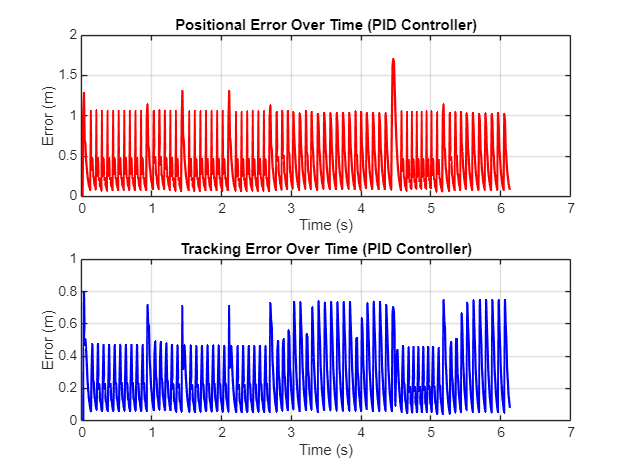


% Plot results
figure;

% Positional Error
subplot(2, 1, 1);
plot((1:length(positionalErrors)) * dt, positionalErrors, 'r', 'LineWidth', 1.5);
title('Positional Error Over Time (PID Controller)');
xlabel('Time (s)');
ylabel('Error (m)');
grid on;

% Tracking Error
subplot(2, 1, 2);
plot((1:length(trackingErrors)) * dt, trackingErrors, 'b', 'LineWidth', 1.5);
title('Tracking Error Over Time (PID Controller)');
xlabel('Time (s)');
ylabel('Error (m)');
grid on;